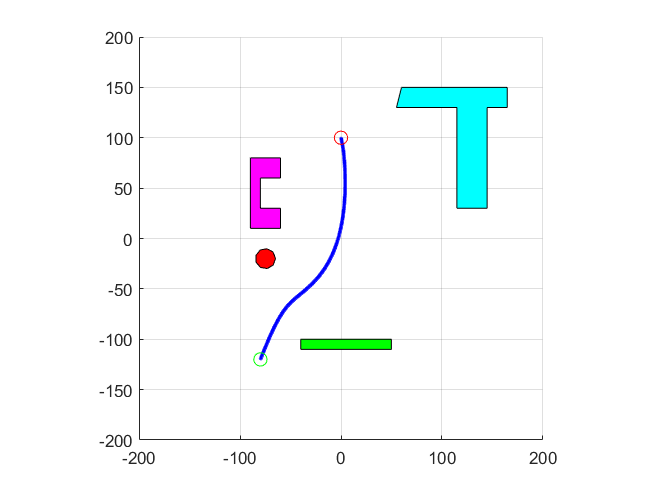

clc;
clear;
c=0;
%constants;
C1=0.04;
C2=0.04;
C3=1000;

%goal point
xg=0;
yg=100;

%step length
s=1;

%start point
xs=-80;
ys=-120;

x=xs;
y=ys;

hold on
%obstacles
%circle 
figure(1);
x_pos=25; 
y_pos=-20; 
r=10; 
t=linspace(1,360,10); 
 
x_component=x_pos+ r*cosd(t); 
y_component=y_pos+ r*sind(t); 
 

% C_Shape 
C_Shape = [-10 10;-10 12;-10 15;-10 17;-10 20;-10 23;-10 25;-10 27;-10 30;-12 30;-15 30;-17 30;-20 30;-22 30;-25 30;-27 30;-30 30;-32 30;-35 30;-37 30;-40 30;-40 27;-40 25;-40 22;-40 20;-40 17;-40 15;-40 12;-40 10;-40 7;-40 5;-40 3;...
    -40 0;-40 -3;-40 -5;-40 -7;-40 -10;-40 -13;-40 -15;-40 -17;-40 -20;-40 -22;-40 -25;-40 -27;-40 -30 ;-40 -32;-40 -35;-40 -37;-40 -40;-35 -40;-30 -40;-25 -40;-20 -40;-15 -40;...
    -10 -40;-10 -20;-30 -20;-30 -18;-30 -16;-30 -14;-30 -12;-30 -10;-30 -8;-30 -6;-30 -4;-30 -2;-30 0;-30 2;-30 4;-30 6;-30 8; -30 10];  
% Bar 
Bar = [-10 -60;-5 -60;0 -60;5 -60;10 -60;15 -60;20 -60;25 -60;30 -60;35 -60;40 -60;45 -60;...
    50 -60;55 -60;60 -60;65 -60;70 -60 ;75 -60;80 -60;80 -65;80 -70;75 -70;70 -70;65 -70;60 -70;55 -70;...
    50 -70;45 -70;40 -70;35 -70;30 -70;25 -70;20 -70;15 -70;10 -70;5 -70;...
    0 -70;-5 -70;-10 -70;-10 -65]; 
%T-Shape
T=[75 -20;80 -20;85 -20;90 -20;95 -20;100 -20;105 -20;...
    105 -15;105 -10;105 -5;105 0;105 2;105 5;105 10;105 15;...
    105 20;105 25;...
    105 30;105 35; 105 40;105 45;105 50;105 55;105 60;...
    105 80;110 80;115 80;120 80;125 80;125 85;125 90;125 95;125 100;120 100;115 100;110 100;105 100;...
    100 100;95 100;90 100;85 100;80 100;75 100;70 100;65 100;60 100;55 100;50 100;...
    45 100;40 100;35 100 ;30 100;25 100 ;20 100;15 80;20 80;25 80;30 80;35 80;40 80;45 80;50 80;55 80;60 80;65 80;70 80; 75 80;75 75;75 70;75 65;...
    75 60;75 55;75 50;75 45;75 40;75 35;75 30;75 25;75 20;75 15;75 10;75 5;75 0;75 -5;75 -10;75 -15];
 
%Moving the shapes tp desired location;

T(:,1)=T(:,1)+40;
T(:,2)=T(:,2)+50;
Bar(:,1)=Bar(:,1)-30;
Bar(:,2)=Bar(:,2)-40;
C_Shape(:,1)=C_Shape(:,1)-50;
C_Shape(:,2)=C_Shape(:,2)+50;
x_component=x_component-100;

% coloring the Obstacles 
fill(x_component,y_component,'r'); 
fill(C_Shape(:,1),C_Shape(:,2),'m') 
fill(Bar(:,1),Bar(:,2),'g'); 
fill(T(:,1),T(:,2),'c');
x_obs=[C_Shape(:,1)' Bar(:,1)' T(:,1)' x_component];
y_obs=[C_Shape(:,2)' Bar(:,2)' T(:,2)' y_component];


d=sqrt((x-xg).^2+ (y-yg).^2);
daspect([2 2 1]);

while(d>2)


d=sqrt((x-xg).^2+ (y-yg).^2);
%D=sqrt((x-x_pos).^2 +(y-y_pos).^2);

%conical force

Fcx=-C1*(x-xg)./d;
Fcy=-C1*(y-yg)./d;

Fqx=0;
Fqy=0;

%quadratic force

if(d<=10)
Fqx=-C2*(x-xg);
Fqy=-C2*(y-yg);

Fcx=0;
Fcy=0;
end  

%Repulsive force

Frx_sum=0;
Fry_sum=0;
for i=1:208

D=sqrt((x-x_obs(i)).^2 +(y-y_obs(i)).^2);
    
 
Frx=C3*(1/(r+5)-1/D)*(1/(D.^3))*(x-x_obs(i));
Fry=C3*(1/(r+5)-1/D)*(1/(D.^3))*(y-y_obs(i));
if (D<=50)
    
end

Frx_sum=Frx_sum+Frx;
Fry_sum=Fry_sum+Fry;

end



Fr=sqrt(Frx_sum.^2+Fry_sum.^2);
%net force


Fx=Fcx+Fqx+Frx;
Fy=Fcy+Fqy+Fry;

thta=atan2(Fy,Fx);
F=sqrt((Fx.^2)+Fy.^2);
x=s*cos(thta)+x;
y=s*sin(thta)+y;
axis([-200 200 -200 200]);
grid on;
plot(x,y,LineWidth=0.5,LineStyle="-",Color='b',Marker='.');
plot(xs,ys,Marker="o",MarkerSize=8,Color='g');
plot(xg,yg,Marker="o",MarkerSize=8,Color='r');
pause (0.000001);
end